

fs = 1e6; % sampling freq
T = 100e-3; % length of the sequence (probe signal) in seconds
r = 25000; % rate
% filter
rolloff = 1/8;



M = r*T;    % number of symbols per sequence
cinit = 1;
anchor1 = genBasebandSig(cinit,M,T,fs,rolloff); % die funktion genBasebandSig ist am ende
cinit = 9;
anchor2 = genBasebandSig(cinit,M,T,fs,rolloff);
cinit = 11;
anchor3 = genBasebandSig(cinit,M,T,fs,rolloff);



% received signal
rx = zeros(1,2*numel(anchor1));
% an dieser stelle werden die signale von den verschiedenen ankern gemixt.
% alle haben unterschiedliche laufzeiten
delay = 0; % delay in seconds
idx = (floor(delay*fs) + 1):(floor(delay*fs) + numel(anchor1) );
rx(idx) = rx(idx) + anchor1;
delay = 20e-3; % delay in seconds
idx = (floor(delay*fs) + 1):(floor(delay*fs) + numel(anchor2));
rx(idx) = rx(idx) + anchor2;
delay = 50e-3; % delay in seconds
idx = (floor(delay*fs) + 1):(floor(delay*fs) + numel(anchor3));
rx(idx) = rx(idx) + anchor3;

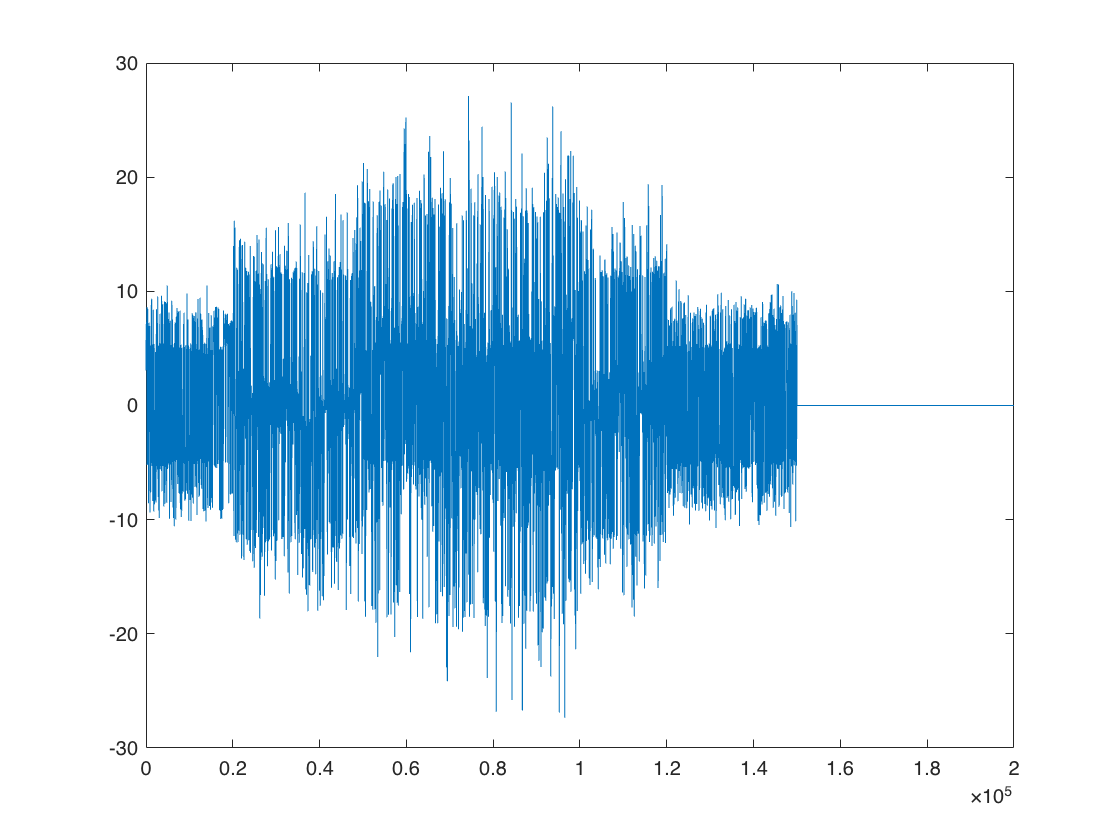


% empfänger sieht nun nur den mix aus verschiedenen signalen:
plot(rx)

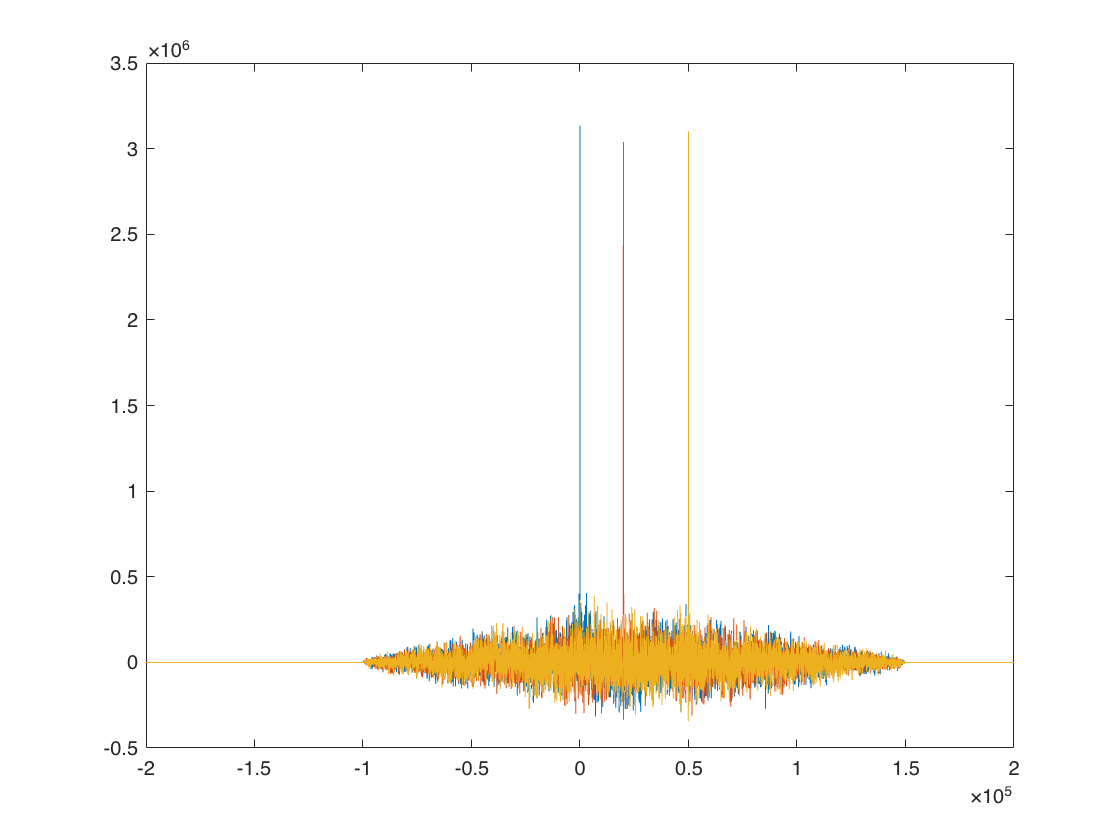


% aus diesem signal muss man nun die einzelnen signallaufzeiten
% herausfinden. dafür benutzt man die kreuzkorrelation r(tau).
%
% die laufzeiten ergeben sich nun aus:
% estimated_delay = arg max(r(tau))
% anchor 1
[r1,tau1] = xcorr(rx,anchor1);
plot(tau1,r1)
hold on;
[r2,tau2] = xcorr(rx,anchor2);
plot(tau2,r2)
[r3,tau3] = xcorr(rx,anchor3);
plot(tau3,r3)
hold off;

[~,idx] = max(r1);
delay1 = tau1(idx)/fs

delay1 = 0


[~,idx] = max(r2);
delay2 = tau2(idx)/fs

delay2 = 0.0200


[~,idx] = max(r3);
delay3 = tau3(idx)/fs

delay3 = 0.0500